# Example 8.1: VHF Push-to-Talk Radio DF

Nicholas O'Donoughue 1 July 2019

*The provided MATLAB contains a sample data set from a set of VHF push-to-talk radios at a standoff range of approximately 50 km, the file can be found with the path *`examples/ex8\_1.mat`*. The data was collected from an array with N=25 elements and *$$d=.5\lambda$$*. Process the data to determine the angle of arrival for the D=3 source signals contained therein.*

## Generate Data

In this live script, let's first generate the data.

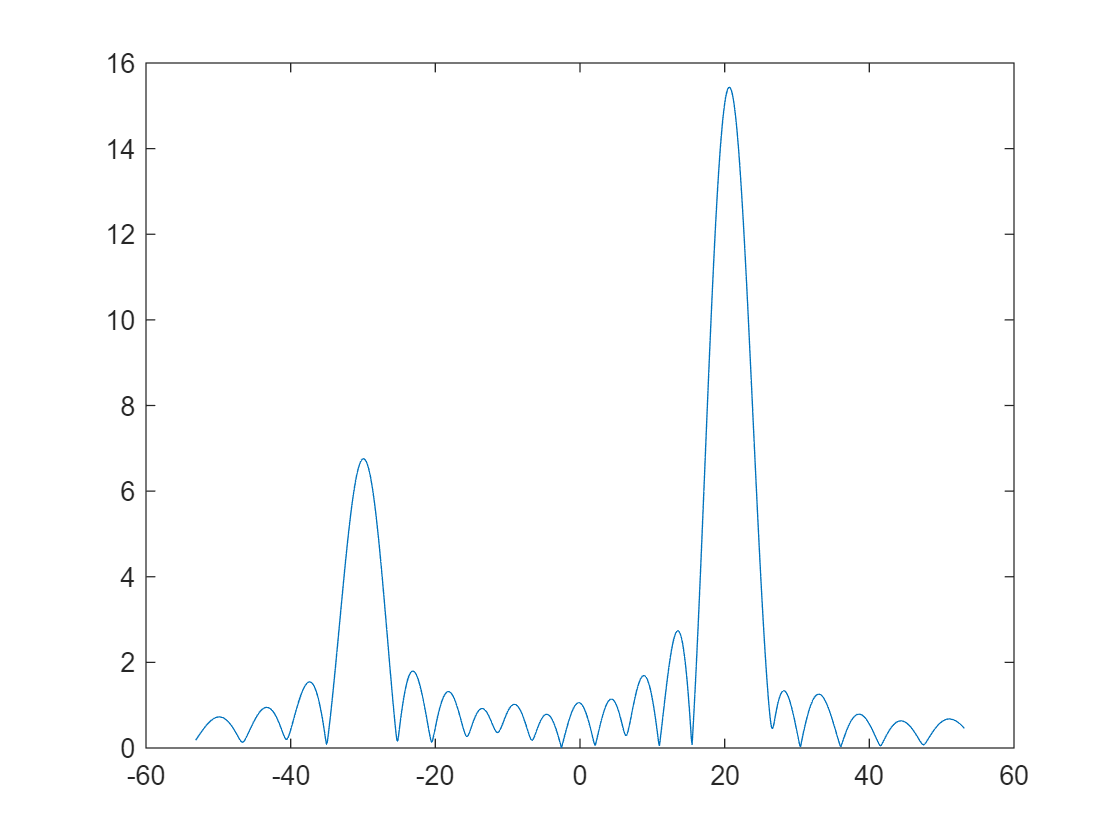

% Initialize PTT Radio Parameters
Pt =     10; % W
Gt =     0; % dBi
Lt =     3; % dB
B_MHz =  0.05; % MHz
B = B_MHz * 1e6; % Hz
ht =     6; % m
f0_MHz = 750; % MHz
f0 = f0_MHz*1e6; % Hz

% Initialize receiver parameters
Gr =     0; % dBi
Lr =     2; % dB
NF =     4; % dB
Br_MHz = 1; % MHz
Br = Br_MHz*1e6;
hr =     1e3; % m
N =      25;  % Num Array elements
M =      100; % Num Time samples
d_lam =  .5; % wavelengths
v = array.make_steering_vector(d_lam,N);

% Initialize source positions
D = 3; % Sources
rng =   [45, 50, 55]*1e3; % m
theta = [-30, 20, 24]; % deg
psi = theta*pi/180;

% Compute Received Power at each element
Lprop = prop.pathLoss(rng,f0,ht,hr,false,[]);
Pr = (10*log10(Pt) + Gt - Lt) - Lprop + Gr - Lr;
N_db = 10*log10(utils.constants.kT*Br)+NF;
SNR = Pr - N_db;
SNR_lin = 10.^(SNR/10); % D x 1
Pr_lin = 10.^(Pr/10);
N_lin = 10.^(N_db/10);

% Set up received data vector
V = v(psi);  % N x D
y = V*(sqrt(Pr_lin(:)/2).*(randn(D,M)+1i*(randn(D,M))));

% Add noise
n = sqrt(N_lin/2)*(randn(N,M)+1i*randn(N,M));
x = (y+n); % N x M

% Compute Array Factor
u_scan = linspace(-.8,.8,1001);
psi_scan = asin(u_scan);
th_scan = psi_scan*180/pi;
AF = array.compute_array_factor(v,x(:,1),psi_scan);
figure;
plot(th_scan,abs(AF));

Normally, we'd save the data, but since we're going to process it in the next section, let's skip that part.

% save examples/ex8_1.mat x D N M d_lam;

## Solution

First, we load the saved data, but in this live script, we've generate the data in the previous section, so there's no need to load it.

% Load sample data
%load('examples/ex8_1.mat','x','D','N','d_lam');
%   x       noisy data vector (M x N)
%   D       number of sources
%   N       number of array elements
%   M       number of time snapshots
%   d_lam   array spacing

`The first step in DOA estimation is setting up the array steering vector and compute the beamscan image. First, we attempt the standard beamformer, with 1,001 sample points between `$$-\pi/2$$` and `$$\pi/2$$`.`

% Construct array steering vector
v = array.make_steering_vector(d_lam,N);

The next step is to find the peaks. If you have the *signal processing toolbox* installed, this is as simple as calling the command `findpeaks`, sorting the returned peaks, and grabbing the D first peaks.

% Call Beamformer
[P,psi_vec] = array.beamscan(x,v,pi/2,1001);

[peak_val,peak_idx] = findpeaks(P,psi_vec);
[~,sort_idx] = sort(peak_val,'descend');
peak_vals = peak_val(sort_idx(1:D));
psi_soln = peak_idx(sort_idx(1:D));
th_soln = 180*psi_soln/pi

th_soln =   -30.0600   20.8800  -37.8000


Note that the first two peaks (at $$-30^\circ$$ and $$20^\circ$$) are picked out with moderate error (the second is off by $$0.52^\circ$$), but the third is picking off a sidelobe of the combined lobe for the two sources near $$20^\circ$$. Hence, it is likely a beamscan imager without knowledge of D would erroneously assume in this case that only two sources exist. Let us repeat the exercise with the MVDR beamformer.

% Call MVDR Beamformer
[P_mvdr,psi_vec] = array.beamscan_mvdr(x,v,pi/2,1001);
[peak_val_mvdr,peak_idx] = findpeaks(P_mvdr,psi_vec);
[~,sort_idx] = sort(peak_val_mvdr,'descend');
peak_vals_mvdr = peak_val_mvdr(sort_idx(1:D));
psi_soln_mvdr = peak_idx(sort_idx(1:D));
th_soln_mvdr = 180*psi_soln_mvdr/pi;

Here, the results accurately line up with the three source locations. We plot the output of these two beamscan beamformers, and the selected peaks, in Figure 8.10.

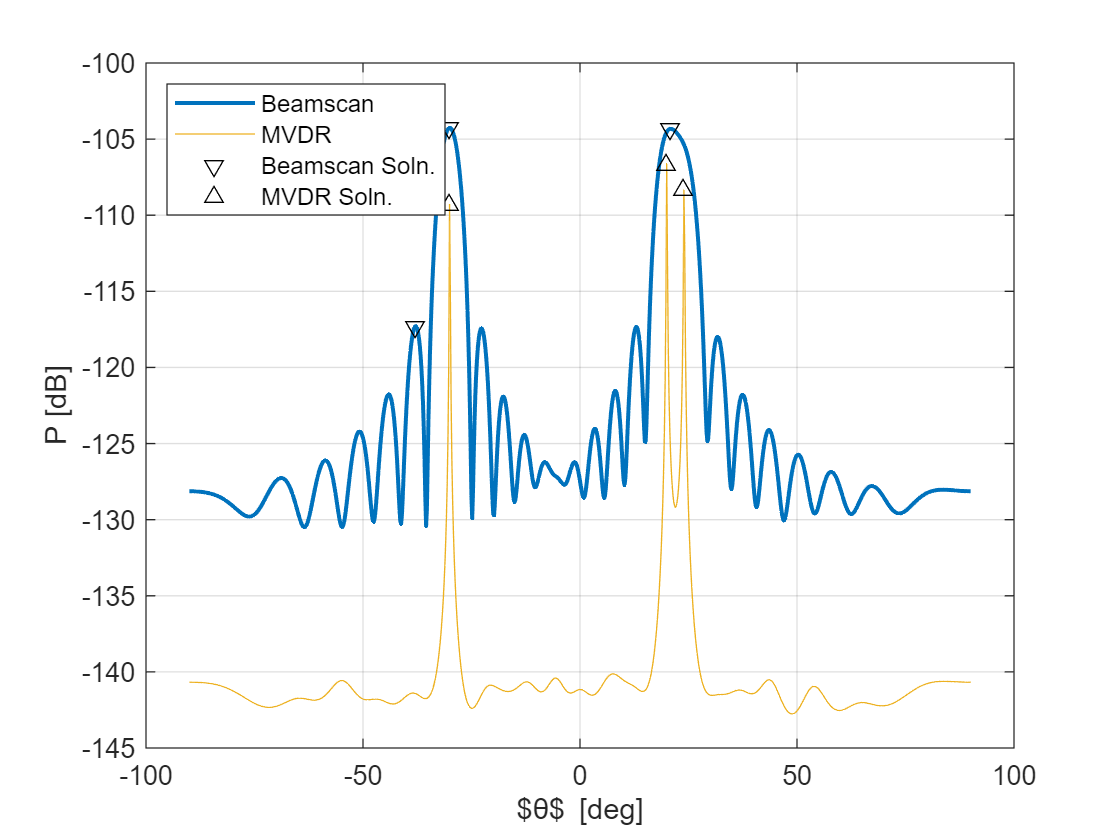

% Plot
th_vec = 180*psi_vec/pi;

fig=figure;
plot(th_vec,10*log10(abs(P)),'LineWidth',1.5,'DisplayName','Beamscan');hold on;
set(gca,'ColorOrderIndex',3);
plot(th_vec,10*log10(abs(P_mvdr)),'DisplayName','MVDR');
plot(th_soln,10*log10(peak_vals),'kv','DisplayName','Beamscan Soln.','MarkerSize',6);
plot(th_soln_mvdr,10*log10(peak_vals_mvdr),'k^','DisplayName','MVDR Soln.','MarkerSize',6);
xlabel('$\theta$ [deg]');
ylabel('P [dB]');
ylim([-145 -100]);
legend('Location','NorthWest');
grid on;